load('loadInData.mat');
data = loadInData;
electrical_load = data.AC;
% Prepare data for training
input_window_size = 168; % 7 days of hourly data
output_window_size = 24; % 1 day ahead prediction
total_window_size = input_window_size + output_window_size;

% Prepare the input and target series
n = length(electrical_load)/input_window_size;
X = [];
T = [];

for i = 1:(n -  1)
    idx=1+(i-1)*input_window_size;
    X{i}(:) =  electrical_load(idx:idx + input_window_size - 1)';
   % T{i}(:) =  electrical_load(idx + input_window_size:idx + total_window_size - 1)';
    T{i}(:) =  electrical_load(idx + 1:idx + input_window_size )';
end
train_ratio = 0.7;
num_train = floor(size(X, 2) * train_ratio);
X_train = X(:, 1:num_train);
T_train = T(:, 1:num_train);
X_test = X(:, num_train+1:end);
T_test = T(:, num_train+1:end);


% X = data.AC(1:end);
% T = data.tstamp(1:end);


net = narxnet(1:2,1:2,10);
[xo,xi,~,to] = preparets(net,X_train,{},T_train);
net = train(net,xo,to,xi);
y = net(xo,xi)

y = 1×33 cell array
    {[151.1772 150.3648 150.9738 149.9848 150.6112 171.3580 177.1471 180.1066 181.4984 182.8619 184.6270 183.8650 187.8657 187.3957 188.8320 189.3580 187.7797 186.2093 148.5234 148.9481 150.8664 151.0194 150.8199 151.9743 150.2931 150.6312 150.7126 151.1099 150.2550 149.8507 150.0294 150.2721 150.1856 150.7899 151.1083 151.3640 151.2085 150.9542 151.1446 150.5265 150.7565 150.5906 150.7868 150.4543 150.6979 150.7867 150.2311 150.3302 150.1856 149.9196 150.5775 150.1547 150.2253 173.2910 186.7669 192.3017 206.0295 209.2847 207.8778 209.5787 210.8265 212.2341 210.2771 206.8795 200.6887 198.9252 154.8737 151.1333 151.5409 152.0940 151.7435 151.7704 151.6540 152.6350 152.2168 152.4335 152.0771 185.6069 194.7812 199.3983 208.4134 209.5358 212.3098 211.4243 211.8490 212.9134 211.3089 210.8683 206.0920 201.4709 157.2895 151.6032 152.7060 152.1947 152.3143 152.4560 152.3190 152.2767 151.7112 151.5348 152.1134 189.4419 196.7534 202.6728 209.3067 212.4762 213.9653 214.0794 21

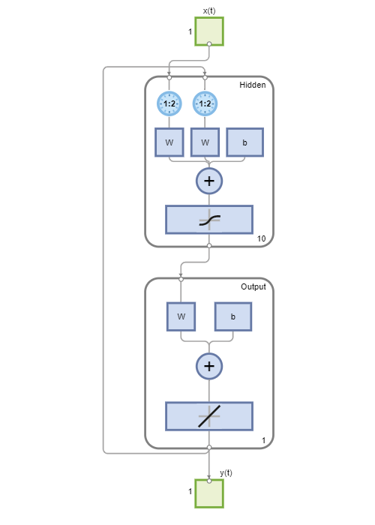



netc = closeloop(net);
view(netc)

[xc,xi,ai,tc] = preparets(netc,X_test,{},T_test);
yc = netc(xc,xi,ai);


T_test_flat = T_test(:);
predictions_flat = yc(:);

mape = mean(abs((T_test_flat - predictions_flat) ./ T_test_flat)) * 100;

Operator '-' is not supported for operands of type 'cell'.

rmse = sqrt(mean((predictions_flat - T_test_flat).^2));

fprintf('MAPE: %.2f%%\n', mape);
fprintf('RMSE: %.2f\n', rmse);
